% driver.m
% Firefighting Drone Swarm Simulation

clear; clc; close all;

% Parameters
params = make_params(); 

% Initialize Fire
fire = init_fire(params);

hotspots =      7     7
     7    24
    24    15


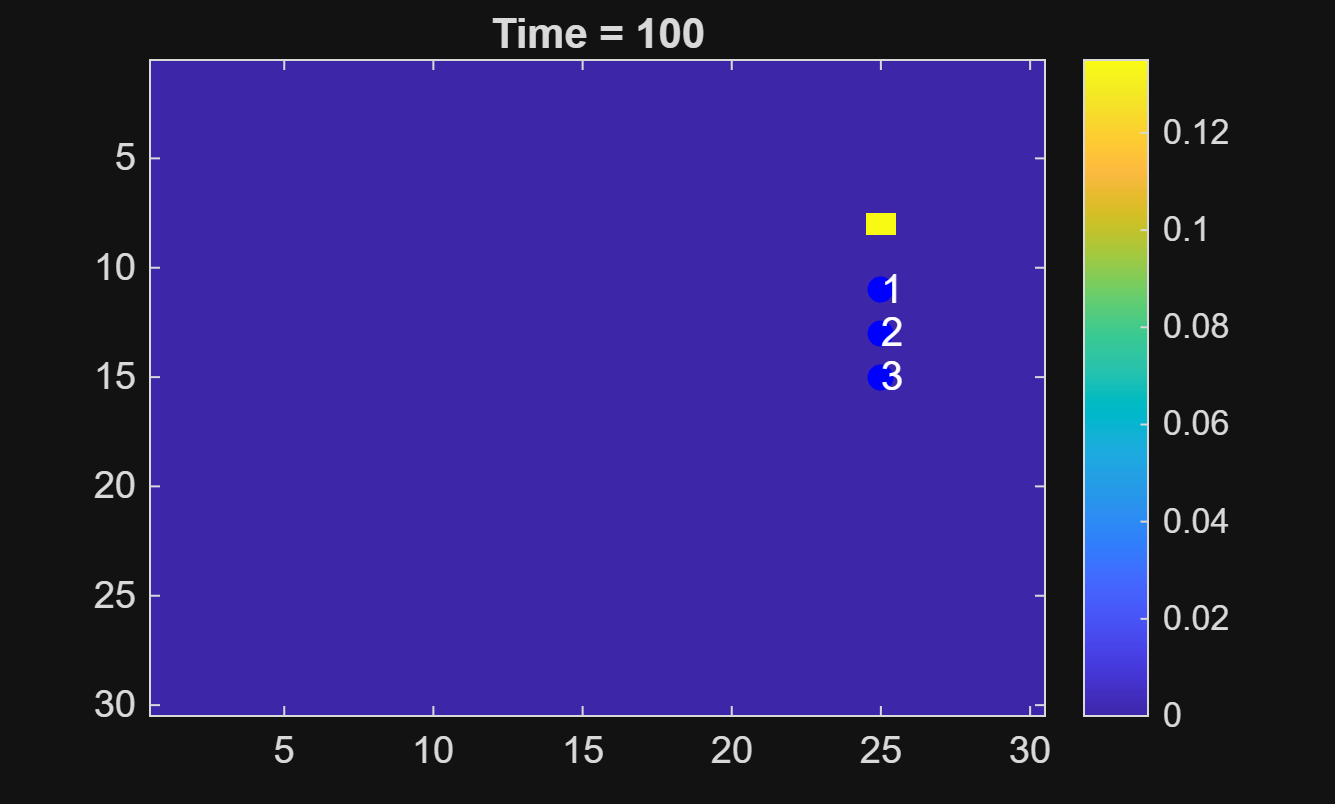

Fire extinguished!



% Initialize Drones
drones = init_Drones(params);

% Simulation Loop
t = 0;

for step = 1 : params.time_limit

    t = t + params.dt;
    fireOut = false;

    oldDrones = drones;
    for i = 1 : length(drones)
        [drones(i), fire] = update_Drone(drones(i), fire, params, oldDrones, i);
    end

    % Fire Update
    fire = fire_step(fire, params);
    
    
    % Visual
    if mod(step, 5) == 0
        imagesc(fire.intensity);
        colorbar;
        title(['Time = ', num2str(t)]);
        hold on;

        for i = 1 : length(drones)
            plot(drones(i).pos(2), drones(i).pos(1), 'bo', 'MarkerFaceColor','b');
            text(drones(i).pos(2), drones(i).pos(1), num2str(i), 'Color','w');
        end

        hold off;
        pause(0.1);
    end

    % Checking fire
    if ~fireOut && max(fire.intensity(:)) < params.fire_thresh
        disp('Fire extinguished!');
        fireOut = true;
        break;
    end
end

% Summary
numDrones = length(drones);

DroneID = (1 : numDrones)';
Distance = zeros(numDrones, 1);
CellsExtinguished = zeros(numDrones, 1);
NearMiss = zeros(numDrones, 1);

for i = 1 : numDrones
    Distance(i) = drones(i).distance;
    CellsExtinguished(i) = drones(i).cells_extinguished;
    NearMiss(i) = drones(i).near_miss;
end

summaryTable = table(DroneID, CellsExtinguished, Distance, NearMiss);

disp(summaryTable);

    DroneID    CellsExtinguished    Distance    NearMiss
    _______    _________________    ________    ________

       1              20             116.85        2    
       2              11             122.58        2    
       3              16              114.2        3    




% Outputs
writetable(summaryTable, 'simulation_summary.csv');

disp('Simulation complete.');

Simulation complete.
